#  CALCULO VECTORIAL

syms x y 

Crea las variables x y para utilizarlas en funciones matemaicas y permite que matlab las reconozca sin necesidad de un valor especifico

## Recta y=x

### plot(x,y)

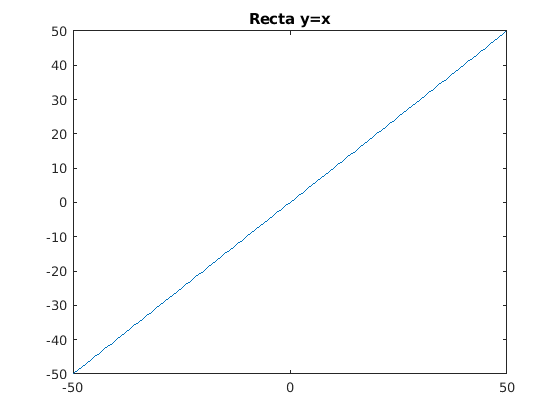

t=-50:1:50;
y=t;
plot(t,y);
title('Recta y=x');

## Curva en el espacio

### comet3(x,y,z)

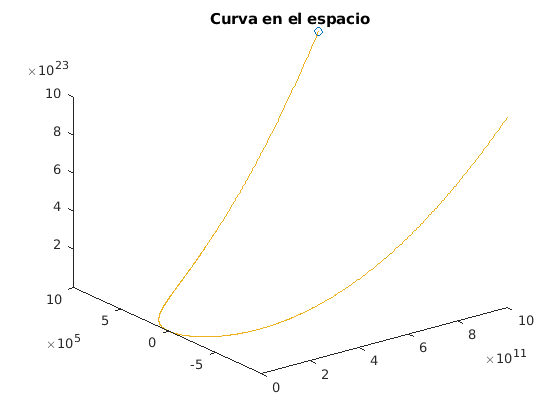

t=-100:0.1:100;
ec1= t.^6+t.^2;
ec2= t.^3+t.^2+t+1;
ec3= t.^12-t.^7+t+1;
comet3(ec1,ec2,ec3);
title('Curva en el espacio');

## Superficie en el espacio

### surf(x,y,z)

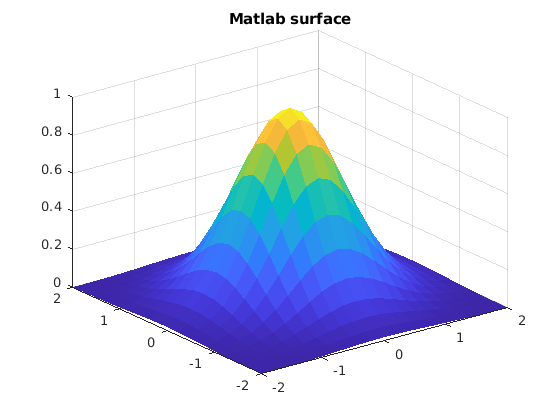

[x,y] =meshgrid(-2:.2:2);
z= exp(-(x.^2+y.^2));
surf(x,y,z);
shading flat
title('Matlab surface')

## PUNTOS, VECTORES Y PLANOS EN R³

## Puntos

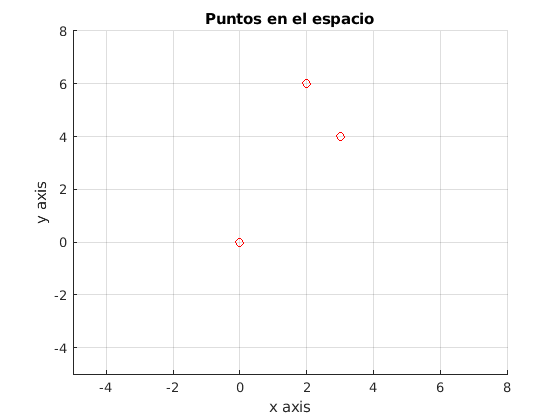

figure
p=[0 0 4]; q=[3 4 8]; r=[2 6 1];
hold on; grid on; rotate3d on;
title('Puntos en el espacio')
plot3(p(1),p(2),p(3),'or');
plot3(q(1),q(2),q(3),'or');
plot3(r(1),r(2),r(3),'or');
xlim([-5 8]); ylim([-5 8]); zlim([-5 8]);
xlabel('x axis'); ylabel('y axis'); zlabel('z axis');

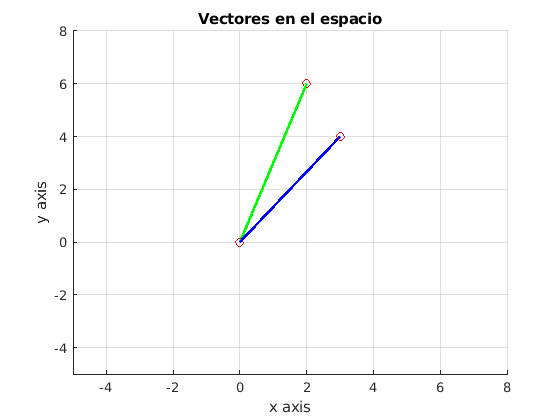


figure
hold on; grid on; rotate3d on;
title('Vectores en el espacio')
plot3(p(1),p(2),p(3),'or');
plot3(q(1),q(2),q(3),'or');
plot3(r(1),r(2),r(3),'or');
xlim([-5 8]); ylim([-5 8]); zlim([-5 8]);
xlabel('x axis'); ylabel('y axis'); zlabel('z axis');
t=linspace(0,1);
v1x= 3*t; v1y= 4*t; v1z= 4*t+4;
v2x= 2*t; v2y= 6*t; v2z= -3*t+4;
plot3(v1x,v1y,v1z,'b','linew',2);
plot3(v2x,v2y,v2z,'g','linew',2);

## Vectores

figure
hold on;grid on; rotate3d on;
title('Plano entre dos vectores')
v1= q-p;
v2= r-p;

t=linspace(0,1);
v1x= 3*t; v1y= 4*t; v1z= 4*t+4;
v2x= 2*t; v2y= 6*t; v2z= -3*t+4;
plot3(v1x,v1y,v1z,'b','linew',2);
plot3(v2x,v2y,v2z,'g','linew',2);

## Vector normal a 2 vectores (producto CRUZ)

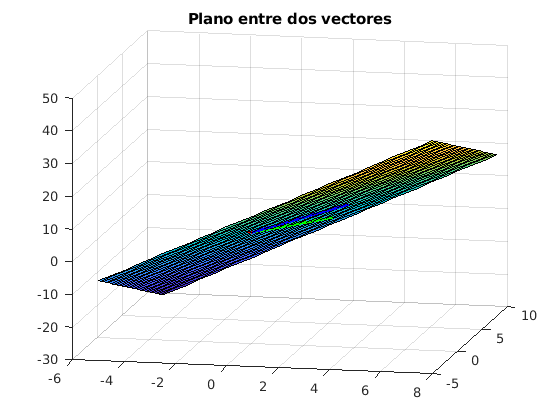

n=cross(v1,v2);
u=n/norm(n);
%create parametric equations to draw u
ux=u(1)*t; uy=u(2)*t; uz=u(3)*t+4;
plot3(ux,uy,uz,'r','linew',2);
%draw the plane: -36(x-0)+17(y-0)+10(z-4)=0
[x,y]=meshgrid(-5:0.5:8);
z=(36.*x-17.*y+40)./10;
surf(x,y,z);